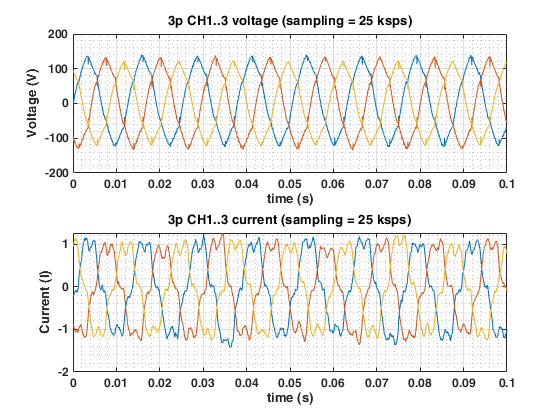

data2plot = meas33;
subplot(2,1,1);
plot(data2plot.Timestamp, data2plot.V_ch1);
hold on;
plot(data2plot.Timestamp, data2plot.V_ch2);
plot(data2plot.Timestamp, data2plot.V_ch3);
grid on; grid minor; xlabel('time (s)'); ylabel("Voltage (V)"); title("3p CH1..3 voltage (sampling = 25 ksps)");
subplot(2,1,2);
plot(data2plot.Timestamp, data2plot.I_ch1);
hold on;
plot(data2plot.Timestamp, data2plot.I_ch2);
plot(data2plot.Timestamp, data2plot.I_ch3);
grid on; grid minor; xlabel('time (s)'); ylabel("Current (I)"); title("3p CH1..3 current (sampling = 25 ksps)");

## análise espectral da tensão/corrente AC 3ph

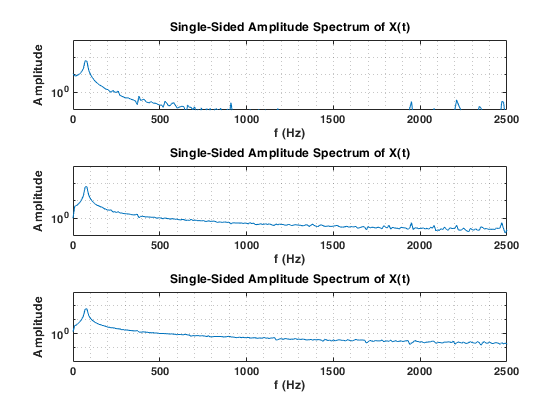

figure;
subplot(3,1,1);
plot_espectral(meas32.V_ch1); xlim([0 2500]); ylim([1e-1 1e3]);
subplot(3,1,2);
plot_espectral(meas32.V_ch2);  xlim([0 2500]); ylim([1e-1 1e3]);
subplot(3,1,3);
plot_espectral(meas32.V_ch3);  xlim([0 2500]); ylim([1e-2 1e3]);

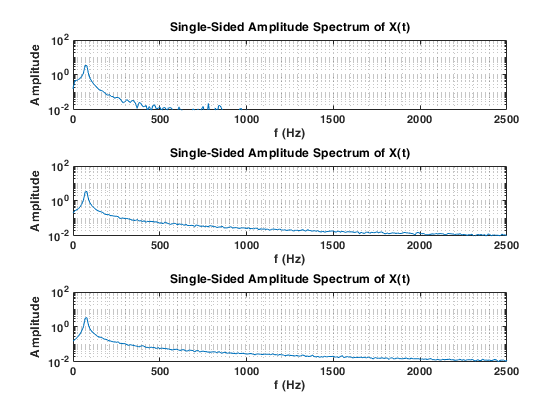

figure;
subplot(3,1,1);
plot_espectral(meas32.I_ch1);  xlim([0 2500]); ylim([1e-2 1e2]);
subplot(3,1,2);
plot_espectral(meas32.I_ch2); xlim([0 2500]); ylim([1e-2 1e2]);
subplot(3,1,3);
plot_espectral(meas32.I_ch3); xlim([0 2500]); ylim([1e-2 1e2]); 

## VECTOR ANALYSIS

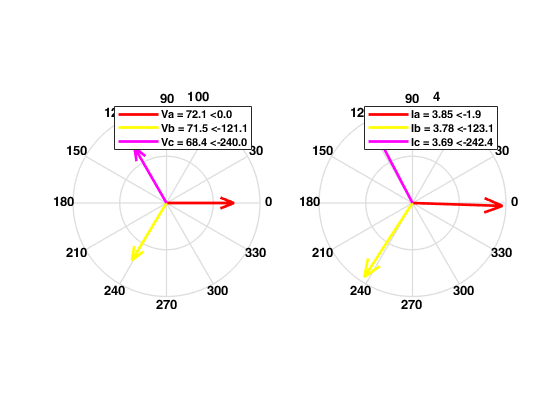

plot_phasor_diagram(meas32);

%plot_aux_phasor_diagram(meas32);

## Functions

function plot_espectral(input_signal)
x = input_signal;
Fs = length(input_signal)*10;
L = length(x);
Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
semilogy(f,P1); grid minor;
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('Amplitude')
% xlim([0 2500]);
% ylim([1e-2 1e3]);
end

function PhDiff = phdiffmeasure(x, y)
%% https://www.mathworks.com/matlabcentral/fileexchange/48025-phase-difference-measurement-with-matlab
% represent the signals as column-vectors
x = x(:);
y = y(:);
% remove the DC component of the signals
x = x - mean(x);
y = y - mean(y);
% signals length calculation
xlen = length(x);
ylen = length(y);
% windows generation
xwin = hanning(xlen, 'periodic');
ywin = hanning(ylen, 'periodic');
% perform fft on the signals
X = fft(x.*xwin); 
Y = fft(y.*ywin);
% fundamental frequency detection
[~, indx] = max(abs(X));
[~, indy] = max(abs(Y));
% phase difference estimation
PhDiff = angle(Y(indy)) - angle(X(indx));
end

function plot_phasor_diagram(meas)
    phase_a = [0 rms(meas.V_ch1)];
    phase_b = [(phdiffmeasure(meas.V_ch1, meas.V_ch2)) rms(meas.V_ch2)];
    phase_c = [(phdiffmeasure(meas.V_ch1, meas.V_ch3)) rms(meas.V_ch3)];
    
    phase_ia = [(phdiffmeasure(meas.V_ch1, meas.I_ch1)) rms(meas.I_ch1)];
    phase_ib = [(phdiffmeasure(meas.V_ch1, meas.I_ch2)) rms(meas.I_ch2)];
    phase_ic = [(phdiffmeasure(meas.V_ch1, meas.I_ch3)) rms(meas.I_ch3)];
    figure;
    subplot(1,2,1);
    title("Voltage phasors");
    [x1,y1] = pol2cart(phase_a(1), phase_a(2));
    c1 = compass(x1, y1);
    c1.LineWidth = 2; c1.Color = 'r';
    hold on;
    [x1,y1] = pol2cart(phase_b(1), phase_b(2));
    c2 = compass(x1, y1);
    c2.LineWidth = 2; c2.Color = 'y';
    [x1,y1] = pol2cart(phase_c(1), phase_c(2));
    c3 = compass(x1, y1);
    c3.LineWidth = 2; c3.Color = 'm';
    legend(strcat("Va = ", num2str(phase_a(2), '%.1f'), " <", num2str(rad2deg(phase_a(1)), '%.1f')),...
        strcat("Vb = ", num2str(phase_b(2), '%.1f'), " <", num2str(rad2deg(phase_b(1)), '%.1f')),...
        strcat("Vc = ", num2str(phase_c(2), '%.1f'), " <", num2str(rad2deg(phase_c(1)), '%.1f')));
    
    subplot(1,2,2);
    title("Current phasors");
    [x1,y1] = pol2cart(phase_ia(1), phase_ia(2));
    c1 = compass(x1, y1);
    c1.LineWidth = 2; c1.Color = 'r';
    hold on;
    [x1,y1] = pol2cart(phase_ib(1), phase_ib(2));
    c2 = compass(x1, y1);
    c2.LineWidth = 2; c2.Color = 'y';
    [x1,y1] = pol2cart(phase_ic(1), phase_ic(2));
    c3 = compass(x1, y1);
    c3.LineWidth = 2; c3.Color = 'm';
    legend(strcat("Ia = ", num2str(phase_ia(2), '%.2f'), " <", num2str(rad2deg(phase_ia(1)), '%.1f')),...
        strcat("Ib = ", num2str(phase_ib(2), '%.2f'), " <", num2str(rad2deg(phase_ib(1)), '%.1f')),...
        strcat("Ic = ", num2str(phase_ic(2), '%.2f'), " <", num2str(rad2deg(phase_ic(1)), '%.1f')));
end

function plot_aux_phasor_diagram(meas)
    VAB = vabc2AB([meas.V_ch1 meas.V_ch2 meas.V_ch3]);
    angle = atan2(VAB(:,2), VAB(:,1)) + pi();
    figure;
    subplot(1,2,1);
    polarplot(angle, meas.V_ch1);
    hold on;
    polarplot(angle, meas.V_ch2);
    polarplot(angle, meas.V_ch3);
    subplot(1,2,2);
    polarplot(angle, meas.I_ch1);
    hold on;
    polarplot(angle, meas.I_ch2);
    polarplot(angle, meas.I_ch3);
end

function VAB = vabc2AB(vabc)
T = 2/3*[ 1   -1/2   -1/2; 0   sqrt(3)/2   -sqrt(3)/2; 1/2  1/2  1/2 ];

VAB = (T*vabc')';
end
